Read a hyperspectral data into the workspace. 

wavelengths=linspace(450,2500,47)

wavelengths = 1.0e+03 *

   0.450000000000000   0.494565217391304   0.539130434782609   0.583695652173913   0.628260869565217   0.672826086956522   0.717391304347826   0.761956521739131   0.806521739130435   0.851086956521739   0.895652173913044   0.940217391304348   0.984782608695652   1.029347826086956   1.073913043478261   1.118478260869565   1.163043478260869   1.207608695652174   1.252173913043478   1.296739130434783   1.341304347826087   1.385869565217391   1.430434782608696   1.475000000000000   1.519565217391304   1.564130434782609   1.608695652173913   1.653260869565218   1.697826086956522   1.742391304347826   1.786956521739131   1.831521739130435   1.876086956521739   1.920652173913044   1.965217391304348   2.009782608695652   2.054347826086957   2.098913043478261   2.143478260869565   2.188043478260870   2.232608695652174   2.277173913043478   2.321739130434783   2.366304347826087   2.410869565217391   2.455434782608696   2.500000000000000


hcube = hypercube('CROP1_47.tiff',wavelengths);

`Now we will use the ECOSTRESS signature library to classify different elements' spectrums`

fileroot = matlabshared.supportpkg.getSupportPackageRoot();
addpath(fullfile(fileroot,'toolbox','images','supportpackages','hyperspectral',...
    'hyperdata','ECOSTRESSSpectraFiles'));

filenames = ["water.seawater.none.liquid.tir.seafoam.jhu.becknic.spectrum.txt",...
    "vegetation.tree.eucalyptus.maculata.vswir.jpl087.jpl.asd.spectrum.txt",...
    "soil.utisol.hapludult.none.all.87p707.jhu.becknic.spectrum.txt",...
    "soil.mollisol.cryoboroll.none.all.85p4663.jhu.becknic.spectrum.txt",...    
    "manmade.concrete.pavingconcrete.solid.all.0092uuu_cnc.jhu.becknic.spectrum.txt"];
lib = readEcostressSig(filenames)

lib = 1×5 struct array with fields:
    Name
    Type
    Class
    SubClass
    ParticleSize
    Genus
    Species
    SampleNo
    Owner
    WavelengthRange
    Origin
    CollectionDate
    Description
    Measurement
    FirstColumn
    SecondColumn
    WavelengthUnit
    DataUnit
    FirstXValue
    LastXValue
    NumberOfXValues
    AdditionalInformation
    Wavelength
    Reflectance


classNames = [lib.Class];

Plot the pure spectral signatures read from the ECOSTRESS spectral library.

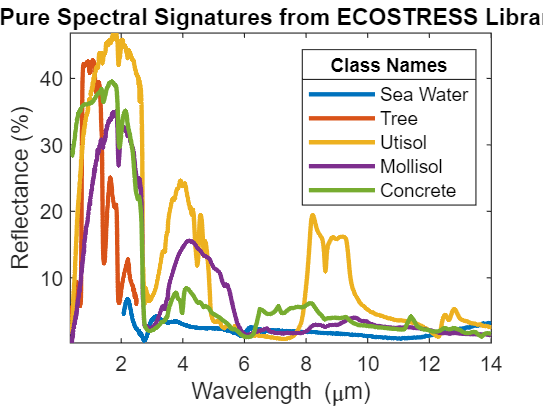

figure
hold on
for idx = 1:numel(lib)
    plot(lib(idx).Wavelength,lib(idx).Reflectance,'LineWidth',2)
end
axis tight
box on
title('Pure Spectral Signatures from ECOSTRESS Library')
xlabel('Wavelength (\mum)')
ylabel('Reflectance (%)')
legend(classNames,'Location','northeast')
title(legend,'Class Names')
hold off

The SAM spectralMatch compares the spectral signatures of the materials differentiated from the ECOSTRESS library to the spectral signatures of the points of the map

scoreMap = spectralMatch(lib,hcube);

Execution of script clib as a function is not supported:
C:\Program Files\MATLAB\R2022a\toolbox\matlab\external\interfaces\cpp\clib.m

figure
montage(scoreMap,'Size',[1 numel(lib)],'BorderSize',10)
title('Score Map Obtained for Each Pure Spectrum','FontSize',14)
colormap(jet);
colorbar

Once this has been done, we can differentiate from the scoreMap the different elements classified, so let's create an association between score Levels and spectral classifications

[~,classMap] = min(scoreMap,[],3);
classTable = table((min(classMap(:)):max(classMap(:)))',classNames',...
             'VariableNames',{'Classification map value','Matching library signature'})

And last, create a single image from all the previous images, and assign labels

fig = figure('Position',[0 0 700 300]);
axes1 = axes('Parent',fig,'Position',[0.04 0 0.4 0.9]);
rgbImg = colorize(hcube,'Method','rgb','ContrastStretching',true);
imagesc(rgbImg,'Parent',axes1);
axis off
title('RGB Image of Data Cube')
axes2 = axes('Parent',fig,'Position',[0.47 0 0.45 0.9]);
imagesc(classMap,'Parent',axes2)
axis off
colormap(jet(numel(lib)))
title('Pixel-wise Classification Map')
ticks = linspace(1.4,4.8,numel(lib));
colorbar('Ticks',ticks,'TickLabels',classNames)     